%计算考虑化学作用后的三锁体系
clear all
syms e r o ;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
l=4;

for l = 4:0.1:6
%计算锁死所占成分
    fun1 = @(x1,x2,x3) P(x3).^2.*P(x2-x3).^2.*P(x1-x2).^2.*P(l-x1);
    x3max= @(x1,x2) 1*x2;
    x2max= @(x1) 1*x1;
    V_lock = 4*integral3(fun1,0,l,0,x2max,0,x3max);

%计算开放所占成分
    fun2 = @(x1,x2,x3) P(l-x3).*P(x3).*P(x2-x3) ...
        .*P(x1-x2).*P(l-x1).*P(x2).*P(x1-x2);
    x3max= @(x1,x2) 1*x2;
    x2max= @(x1) 1*x1;
    V_open1 = 2*integral3(fun2,0,l,0,x2max,0,x3max);
    fun3 = @(x1,x2,x3) P(l-x2).*P(x3).*P(x2-x3) ...
        .*P(x1-x2).*P(l-x1).*P(x3).*P(x1-x3);
    x3max= @(x1,x2) 1*x2;
    x2max= @(x1) 1*x1;
    V_open2 = 2*integral3(fun3,0,l,0,x2max,0,x3max); 
    V_open=V_open1 + V_open2;
    P_lock = V_lock/(V_lock + V_open) %计算锁死所占比例
    Plock=[Plock,P_lock];
end

P_lock = 0.2856

P_lock = 0.7653

P_lock = 0.9068

P_lock = 0.9568

P_lock = 0.9759

P_lock = 0.9793

P_lock = 0.9787

P_lock = 0.9761

P_lock = 0.9724

P_lock = 0.9679

P_lock = 0.9631

P_lock = 0.9585

P_lock = 0.9543

P_lock = 0.9507

P_lock = 0.9476

P_lock = 0.9449

P_lock = 0.9426

P_lock = 0.9406

P_lock = 0.9387

P_lock = 0.9371

P_lock = 0.9355

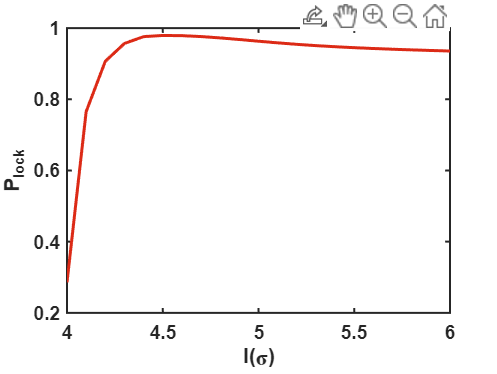



%画出锁死概率随l的变化
length=[4:0.1:6];
plot(length, Plock,'LineWidth',1.5, ...
    'color',[221, 42, 22]/256)


set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('P_{lock}','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=5500;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end
